# A demo for generating hand written-like numbers using variational autoencoder  

This demo generates a hand-written number gradually changing from 0 to1. Also, other numbers (MNIST) are available for the generation. The official documentation entitled "Train Variational Autoencoder (VAE) to Generate Images" was reffered for this demo as shown below.  

([https://jp.mathworks.com/help/deeplearning/examples/train-a-variational-autoencoder-vae-to-generate-images.html](https://jp.mathworks.com/help/deeplearning/examples/train-a-variational-autoencoder-vae-to-generate-images.html)) 

## Loading data

The data used here in this demo can be derived after running the code below. Since the dataset does not belong to me, I do not attach the data. The variables derived from the data after some calculation process are attached. Please load them in this section. Note that the process in the documentation below requires a few hours: to try this demo and get futher information from the official document is recommended. 

[https://jp.mathworks.com/help/deeplearning/examples/train-a-variational-autoencoder-vae-to-generate-images.html](https://jp.mathworks.com/help/deeplearning/examples/train-a-variational-autoencoder-vae-to-generate-images.html)

The three variables should be imported first which are z value in the latent space corresponding to 0 and 1 and the decorder. 

clear;clc;close all
load  zSampled_start.mat 
load  zSampled_goal.mat 
load  decoderNet

## Imposing a probability distribution on the latent space

- Retrieve the hand-written data of 0 and 1 to calculate the probability distribution in on the latent space for this demo

- If you would like to try with other digits, please run the code in the official document above and obtain the variable `XTrain`. 

- When trying this with other numbers, pls set the variable` skip `to  0, otherwise, the pre-calculated data for generating 0 and 1 will be used.  

- Specify the digits to generate with the variable `start `and `goal`

start=0;
goal=1;
skip=1;
if skip==0
    start_idx=find(YTrain==categorical(start));
    goal_idx=find(YTrain==categorical(goal));
    XTrain_start=XTrain(:,:,:,start_idx);
    XTrain_goal=XTrain(:,:,:,goal_idx);
    [zSampled_start, zMean_start, zLogvar_start] = sampling(encoderNet, XTrain_start);
    [zSampled_goal, zMean_goal, zLogvar_goal] = sampling(encoderNet, XTrain_goal);    
end

## Dimensional reduction using t-SNE 

- The latent space was defined by the mean and variance metrix 

- The mean and variance metrix returns the sampled values

- Those values were visualized in the 2D space using a dimension reduction method called t-SNE. 

- Other dimension reduction methods are available such as PCA (Principal Component Analysis) and UMAP. 

- Use` extractdata` function to retrieve values in the `dlarray `variable 

- Here, the function `tsne` was simply carried out. For the detail of the parameters in t-sne (t-distributed stochastic neighbor embedding), pls refer to the official document as follows. ([https://jp.mathworks.com/help/stats/tsne.html](https://jp.mathworks.com/help/stats/tsne.html))

- For the further information of the t-SNE, pls refer this document made by Federico Errica  ([http://pages.di.unipi.it/errica/assets/files/sne_tsne.pdf](http://pages.di.unipi.it/errica/assets/files/sne_tsne.pdf))

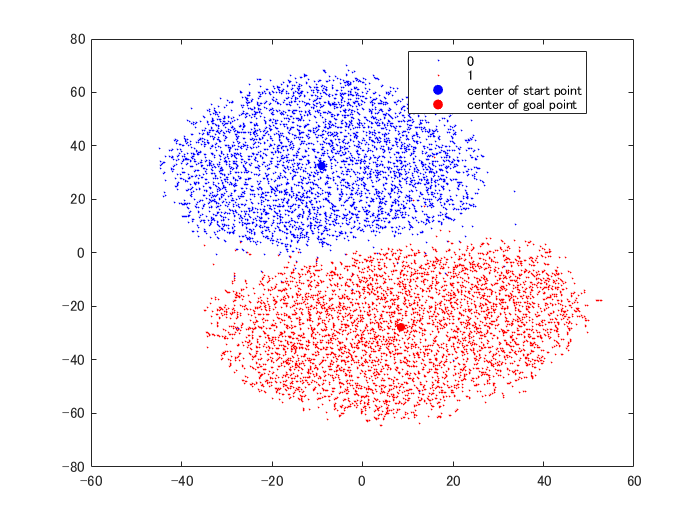

start_to_tsne =transpose(squeeze(extractdata(zSampled_start)));
goal_to_tsne = transpose(squeeze(extractdata(zSampled_goal)));
result_tsne=tsne([start_to_tsne;goal_to_tsne],'NumPCAComponents',10);
labels=[zeros(size(start_to_tsne,1),1);ones(size(goal_to_tsne,1),1)];
figure;gscatter(result_tsne(:,1),result_tsne(:,2),categorical(labels),'br','xx',1);hold on
start_tsne=result_tsne(1:size(start_to_tsne,1),:);
goal_tsne=result_tsne(size(start_to_tsne,1)+1:end,:);
centroid_start=mean(start_tsne,1);
centroid_goal=mean(goal_tsne,1);
s_start=scatter(centroid_start(1),centroid_start(2),25,'b','filled');
s_start.DisplayName='center of start point';
hold on
s_goal=scatter(centroid_goal(1),centroid_goal(2),25,'r','filled');
s_goal.DisplayName='center of goal point';hold on

## Generating the handwritten-like numbers which gradually is changing from 0 to 1

The procedure generating the handwritten-like numbers follows:

- The mean value of the sampled data was calculated. 

- The data to decord was made using the mean value from 0 and 1 data.

- First, the image was reconstructed using the value in the centroid of latent space from "0"

- Gradually, the latent space to use was moved to the centroid of the latent space from "1". 

*Note that the moving dot in the 2D space was just a mark that implies how the sampled value from the latent space is close to / far from the centroid of the latent values from 0 and 1.  

*To display the progress of the generation, "For-loop" is used here, however, the calculation can be done without the loop for the faster calculateion if necessary. 

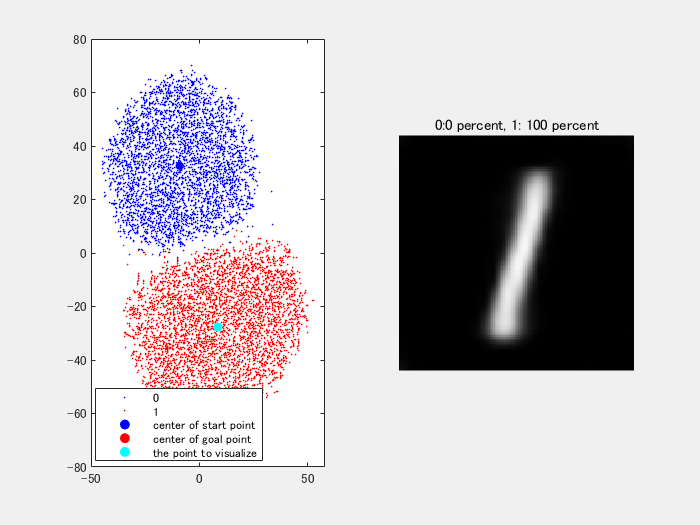

mean_start=mean(zSampled_start,4);
mean_goal=mean(zSampled_goal,4);
figure;set(gcf,'Visible','on')
interval=100;% it controls the step from 0 to 1. Decrease this value to implement faster 
for i=1:interval
subplot(1,2,1)
gscatter(result_tsne(:,1),result_tsne(:,2),categorical(labels),'br','xx',1);hold on
s_start=scatter(centroid_start(1),centroid_start(2),25,'b','filled');
s_start.DisplayName='center of start point';
hold on
s_goal=scatter(centroid_goal(1),centroid_goal(2),25,'r','filled');
s_goal.DisplayName='center of goal point';hold on
point=(centroid_goal-centroid_start).*i./interval+centroid_start;
s_point=scatter(point(1),point(2),30,'c','filled');
s_point.DisplayName='the point to visualize';
hold off

input=(mean_goal-mean_start).*i./interval+mean_start;
xPred_start = sigmoid(forward(decoderNet, input));
xPred_start_single=extractdata(xPred_start);
subplot(1,2,2)
imshow(imresize(xPred_start_single,5))
ta=round((interval-i)./interval*100);
tb=round((i/interval)*100);
ratio=sprintf('0:%d percent, 1: %d percent',ta,tb);
title(ratio)
drawnow
hold off
F(i) = getframe(gcf) ;
end

## Save the process of the generation into a movie file

- You can save it as GIF file, too if you want

- Pls specify the name of the video to save with the string in the blacket after `VideoWriter`. 

writerObj = VideoWriter('myVideo.avi');
  writerObj.FrameRate = 10;
% set the seconds per image
% open the video writer
open(writerObj);
% write the frames to the video
for i=1:length(F)
    % convert the image to a frame
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
% close the writer object
close(writerObj);

## Future perspectives

- Other methods can be considered to extract the value on the latent space to generate a digit more clearly while the centroid of the values on the latent space were simply used.

- Images other than hand-written digits will be generated with this code

## Sub-function：sampling

This sub-function was obtained from the official document located at ([https://jp.mathworks.com/help/deeplearning/examples/train-a-variational-autoencoder-vae-to-generate-images.html](https://jp.mathworks.com/help/deeplearning/examples/train-a-variational-autoencoder-vae-to-generate-images.html))

- This function is called when you would like to generate the digits not used in this demo, namely 0 and 1.

- First, it encodes the input images

- Then, this function implements the reparametrization trick to get the sampled values 

function [zSampled, zMean, zLogvar] = sampling(encoderNet, x)
compressed = forward(encoderNet, x);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
z = reshape(z, [1,1,sz]);
zSampled = dlarray(z, 'SSCB');
end